S = 20; % size of symbols in pixels
% normalize vector to go from zero to 1
normV = (data.t-min(data.t))./(max(data.t)-min(data.t))

normV =          0
    0.0244
    0.0284
    0.0289
    0.0294
    0.0306
    0.0311
    0.0316
    0.0321
    0.0326


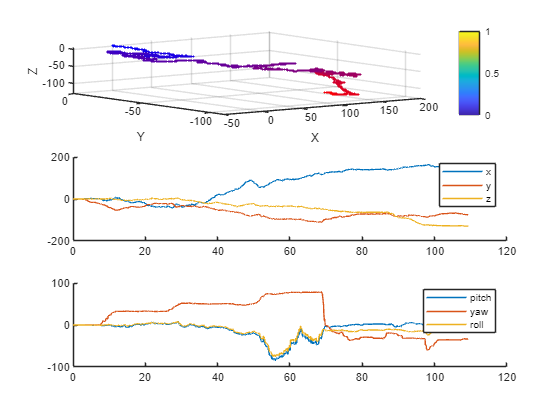

% blue to red. 
C = [normV zeros(size(normV)) 1-normV];

% jet colors
CC = jet(numel(normV));


figure
subplot(3,1,1)
scatter3(data.x, data.z, data.y, S, C,'Marker', '.')
colorbar('vert')
xlabel('X')
ylabel('Y')
zlabel('Z')
subplot(3,1,2)
hold on
plot(data.t,data.x)
plot(data.t,data.z)
plot(data.t,data.y)
legend(["x" "y" "z"])
subplot(3,1,3)
hold on
plot(data.t,data.pitch)
plot(data.t,data.yaw)
plot(data.t,data.roll)
legend(["pitch" "yaw" "roll"])

ax = figure

ax =   Figure (30) with properties:

      Number: 30
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


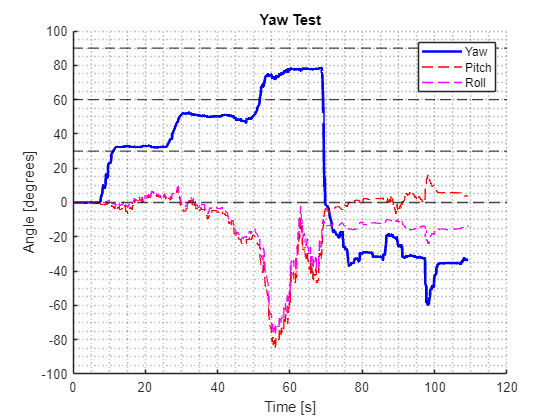

clf
hold on
plot(data.t, data.yaw, "b", LineWidth=2)
plot(data.t, data.pitch, "r--", LineWidth=1)
plot(data.t, data.roll, "m--", LineWidth=1)
yline(0, 'k--', LineWidth=1)
yline(30, 'k--', LineWidth=1)
yline(60, 'k--', LineWidth=1)
yline(90, 'k--', LineWidth=1)

legend(["Yaw" "Pitch" "Roll"])

ylim([-100 100])

grid minor
xlabel("Time [s]")
ylabel("Angle [degrees]")
title("Yaw Test")

exportgraphics(ax, "outputs\plots\yaw.png", Resolution=900)

ax = figure

ax =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [1000 818 560 420]
       Units: 'pixels'

  Show all properties


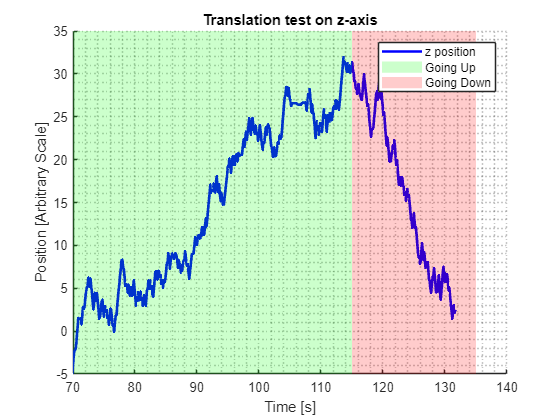

clf
hold on
plot(data.t, -data.z, "b", LineWidth=2)
area([60 60 115 115], [-6 40 40 -6],-6,FaceColor="g", FaceAlpha=0.2,EdgeAlpha=0)
area([115 115 135 135], [-6 40 40 -6],-6,FaceColor="red", FaceAlpha=0.2,EdgeAlpha=0)

legend(["z position" "Going Up" "Going Down"])

ylim([-5 35])
xlim([70 140])
grid minor
xlabel("Time [s]")
ylabel("Position [Arbitrary Scale]")
title("Translation test on z-axis")

exportgraphics(ax, "outputs\plots\z.png", Resolution=900)